# Part 4: Noise Removal

This script explores noise removal, first in principal, by applying it to sample data and seeing the effects visually; then by applying it prior to the model building phase. 

For this demo, we'll build the same models as in Part 3. Alternatively - and more typically as the first, not later step in building models - you may apply noise removal prior to building models on the signal itself, without extracting features.

## Load and Prepare Data

rng;

% load the a "small" subset of the raw sensor data
% Note: it is small indeed, comprising of 650 compared to the >17k samples used in Part2, 
% and the features for the full data set extracted into FeatureEntire.mat. 
% "MachineData.mat" - maybe not aptly named - is a tiny subset of 40 samples, chosen so that feature extraction
% runs fast in a demo setting.
load("MachineDataSmall.mat");

% show breakdown into abnormal vs normal
st=groupsummary(trainSmall,'label')

st = 2×2 table
     label     GroupCount
    _______    __________

    Anomaly        74    
    Normal        576    



tF = trainSmall.label == "Normal";    % get the indices of the data "after" maintenance
abnormalData = trainSmall(~tF,:);
normalData = trainSmall(tF,:);

## Removing Noise

Instead of re-using the features, we could start with the original data and apply standard data preprocessing stage in preparation for some advanced feature engineering. 

To address problems with sensor outage and noise, we can smoothen the data and apply noise filtering. 

### Noise Filtering with Smooth Data Live task

The Smooth Data Live Task lets you explore that interactively. Watch how moving average and Gaussian filters really even out edges in the signal. 

Below we apply noise filtering to data from channel 1, whose shape is visually distinct so you can better see the effect of noise filtering.

% grab a sample of the data, e.g. channel 1 from the 2nd 'before' (abnormal) observation
abnormSample = abnormalData.ch1{2};


% now let's apply smoothing interactively to 'abnormSample'

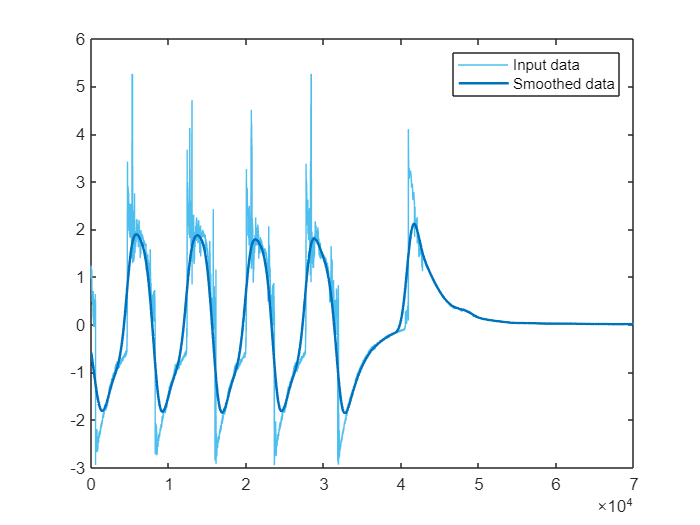

% Smooth input data
smoothedData = smoothdata(abnormSample,"gaussian","SmoothingFactor",0.25);

% Display results
clf
plot(abnormSample,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

Those edges, however, can contain discriminating information, i.e. that's important for correction predictions .

Therefore, advanced noise removal techniques try to preserve edges, while also addressing non-gaussian noise. Savitzky-Golay locally fits polynomials against the signal. This - and also the much simpler median filter - can remove non-gaussian noise and better preserve the edges of the signal. *(Go back to the Live Task and select Smoothing Method = "Savitzky-Golay" if you prefer to try youself)*.

### Noise Removal with Wavelet Denoising

Another  advanced techniques that ecels at preserving edges and features is [Wavelet denoising](https://www.mathworks.com/help/wavelet/ug/wavelet-denoising.html). 

Either open the Wavelet Signal Denoiser app and try it yourself interactively, or you can see the effects on above signal from the code below.

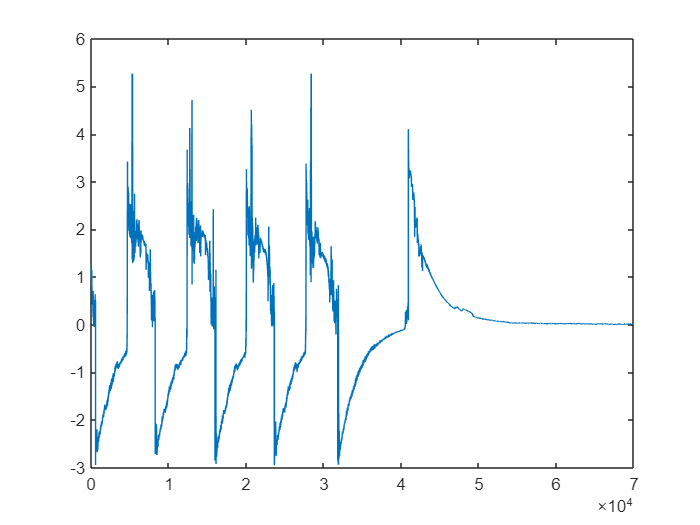

abnormWavelet = wdenoise(abnormSample,5, ...
    'Wavelet', 'sym4', ...
    'DenoisingMethod', 'Bayes', ...
    'ThresholdRule', 'Median', ...
    'NoiseEstimate', 'LevelDependent');
plot(abnormWavelet);

### Remove Noise on whole Data Set

Next, we'll remove noise on the whole data set. Considering the three channels, the signals for the normal and anomalous conditions are significantly different for channel 1 and channel 2, while they are more similar on channel 3.

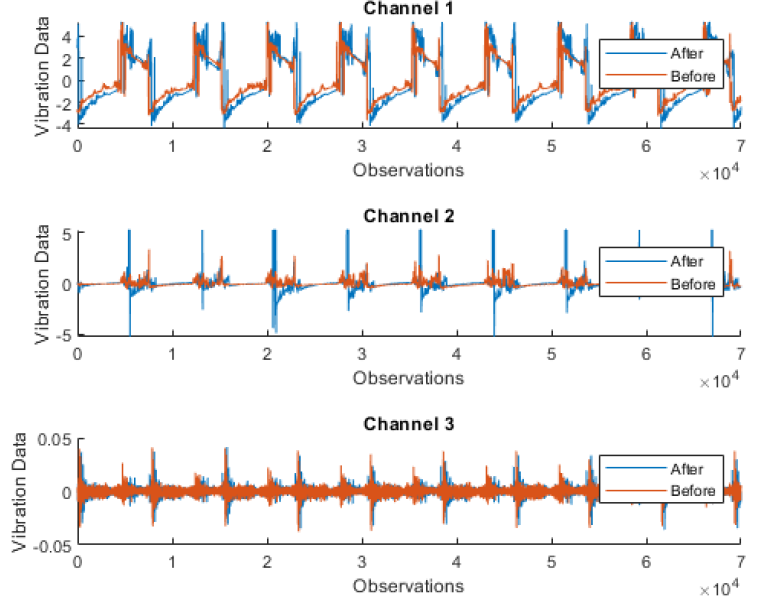 

Therefore, we'll apply noise filtering to channel 3 only, at least for starters. You may question this assumption later.

To experiment yourself, you can modify the method to apply below, but you'll have to wait a few minutes for processing to finish: first the noise filtering, and then apply feature extraction. *Note: For simplicity, we extract the same features as illustrated in Part 1. For optimal performance on your data, you may have to revisit the selection of features.*

Or jump to the section where we load the data after noise was removed and features were extracted.

% apply noise filter as indicated by <method> (any valid method supported
% by smoothdata, or 'wavelet' for wavelet denoising
method = "movmedian"

method = "movmedian"


% start a new table to hold the smoothened (filtered) data
trainSmallSmooth = table;
dataN = height(trainSmall);
warning off;                  % don't display warnings about not assigning values to ch2, ch3 with each new row

for i = 1:dataN
    % apply filter to each observation separately
    switch method
        case 'wavelet'
            trainSmallSmooth.ch3{i} = wdenoise(trainSmall.ch3{i},5, 'Wavelet', 'sym4', 'DenoisingMethod', 'Bayes', ...
                'ThresholdRule', 'Median', ...
                'NoiseEstimate', 'LevelDependent');
        otherwise % assume method is supported by smoothdata
            trainSmallSmooth.ch3{i} = smoothdata(trainSmall.ch3{i},method);
    end
end
% simply copy channel 1 + 2 unmodified (until you decide to change)
trainSmallSmooth.ch1 = trainSmall.ch1;
trainSmallSmooth.ch2 = trainSmall.ch2;

% NOTE: we already renamed labels from 'Before'/'After' maintenance to
% 'Anomaly'/'Normal' during preprocessing of this smaller data set
trainSmallSmooth.label = trainSmall.label;

% extract features - like above - from (noise) filtered data.
% generateFeatures applies the feature extraction developed in Part1, based
% on the Diagnostic Feature Designer
featureSmallSmooth = generateFeatures(trainSmallSmooth);

Load data with noise removed and features extracted , instead of executing it above.

if ~exist('method')
    load("FeatureNoiseRemoved.mat");
    switch method
        case 'wavelet'
            featureSmallSmooth = featureWavelet;
        case 'median'
            featureSmallSmooth = featureMedian;
        otherwise
            disp("Choose one of the pre-loaded noise filtering techniques: wavelet, median")
    end
end

## Apply Unsupervised Anomaly Detection after Noise Removal

Unless you switch the workflow to building models on the signal data without feature extraction - which is something you may try - we still need to extract features (done above), and for simplicity the same as before, and divide the data into train versus held-out test.

% divide subset into train and (held out) test using same partition as in
% other script (if available)
if ~exist('idxSmall')
    idxSmall = cvpartition(featureSmallSmooth.label,'holdout',0.2);
end
featSmallSmoothTrain = featureSmallSmooth(idxSmall.training,:);
featSmallSmoothTest = featureSmallSmooth(idxSmall.test,:);

### One-Class SVM after Noise Removal

Like in Part 3, we build a one-class SVM to identify the anomalies.

% identify subset of "normal" (healthy) data in training 
healthyIdx = featSmallSmoothTrain.label=='Normal';
trainHealthy = featSmallSmoothTrain(healthyIdx,2:13);   % can safely skip labels column since all are normal / 'After' (maintenance)
trainHealthyN = size(trainHealthy,1);

% train one-class SVM. On this data, training just on the "normal" (healthy) data works better
mdlSVM = fitcsvm(trainHealthy,ones(trainHealthyN,1),'Standardize',true,'OutlierFraction',0);
% this variant trains on all data (including anomalies), with the estimated fraction
%mdlSVM = fitcsvm(featSmallTrain(:,2:13),ones(size(featSmallTrain,1),1),'Standardize',true,'OutlierFraction',outlierFraction);

% apply to "small" test data (which has both anomalies and healthy data)
[~,scoreSVM] = predict(mdlSVM,featSmallSmoothTest(:,2:13));
isanomalySVM = scoreSVM<0;
predSVM = categorical(isanomalySVM, [1, 0], ["Anomaly", "Normal"]);


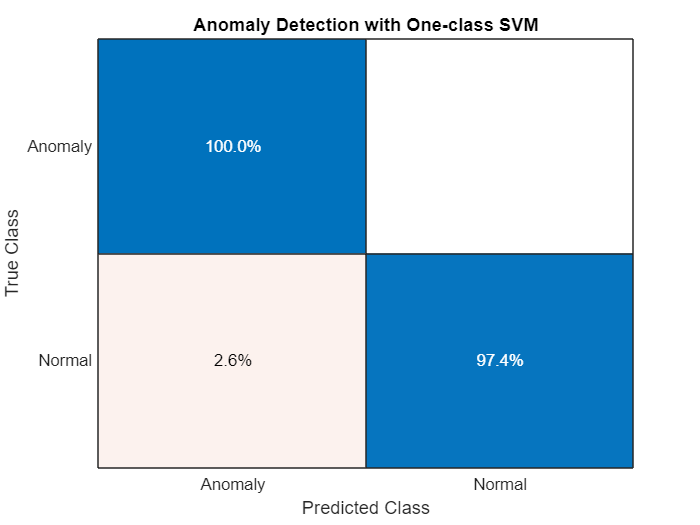

confusionchart(featSmallSmoothTest.label,predSVM,Title="Anomaly Detection with One-class SVM",Normalization="row-normalized");

Without noise removal and one-class SVM, we misclassified 3% of 'normal' samples as anomalous. With noise removal, we reduced that "false detection" (of anomalies) by about 1 point, or 25%.

### Isolation Forest after Noise Removal

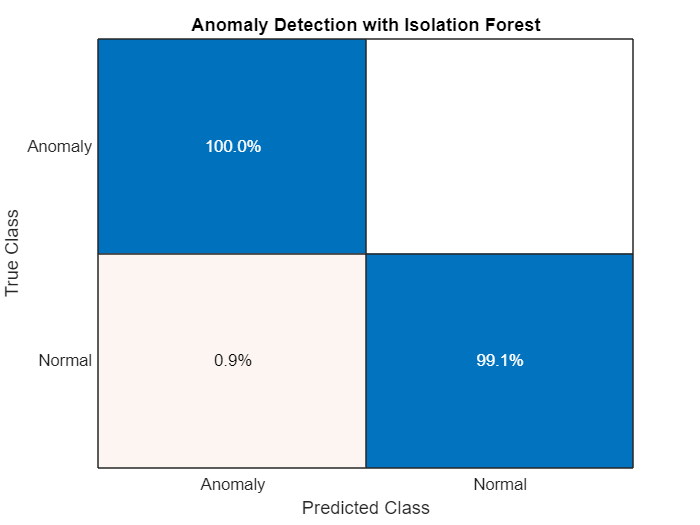

% train on normal (healthy) data only. Need to tune the ContimationFraction!
%outlierFraction = st.GroupCount(1)/size(trainSmall,1); this is the actual
% fraction in the data, but we're missing some anomalies.
[mdlIF,~,scoreTrainIF] = iforest(trainHealthy,'ContaminationFraction',0.05);

[isanomalyIF,scoreTestIF] = isanomaly(mdlIF,featSmallSmoothTest(:,2:13));
predIF = categorical(isanomalyIF, [1, 0], ["Anomaly", "Normal"]);

confusionchart(featSmallSmoothTest.label,predIF,Title="Anomaly Detection with Isolation Forest",Normalization="row-normalized");

Without noise removal and isolation forest, we misclassified 5% of 'normal' samples as anomalous. With noise removal, we reduced that "false detection" (of anomalies) to 1%.

## Summary

We presented various options for noise removal, including interactive Smooth Data Live task that offers a variety of noise filtering techniques, and advanced noise removal applying wavelet denoising.

Noise removal reduced false detection of anomalies for some method but not across the board. Whether it helps, and which method works best will vary depending on your data.

*Copyright 2021 The MathWorks, Inc.*